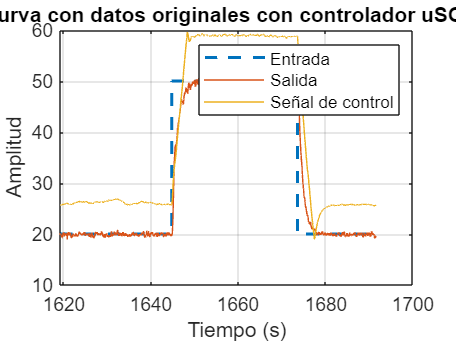

datos1 = readmatrix('usort_PI.xlsx');
datos2 = readmatrix('usort_PI.xlsx','Range','A1052:D3050');

t = datos1(:,1);
r = datos1(:,2);
y = datos1(:,3);
u = datos1(:,4);

figure(1)
plot(t, r,'--', LineWidth=1.5)
hold on
plot(t, y, t, u);
title('Curva con datos originales con controlador uSORT')
legend('Entrada', 'Salida', 'Señal de control')
xlabel('Tiempo (s)')
ylabel('Amplitud')
grid on
hold off

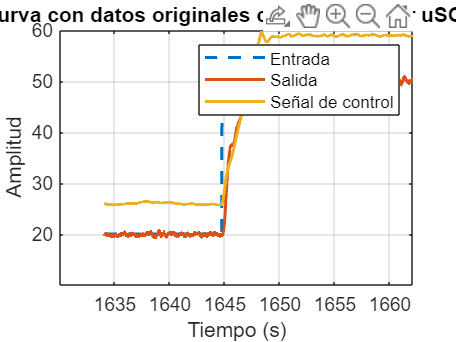



t2 = datos2(:,1);
r2 = datos2(:,2);
y2 = datos2(:,3);
u2 = datos2(:,4);

figure(2)
plot(t2, r2,'--', LineWidth=1.5)
hold on
plot(t2, y2, t2, u2, LineWidth=1.5);
title('Curva con datos originales con controlador uSORT')
legend('Entrada', 'Salida', 'Señal de control')
xlabel('Tiempo (s)')
ylabel('Amplitud')
grid on
hold off

# Sobrepaso máximo porcentual

yf = mean(y2(1199:1999))

yf = 49.9894


Mpn = (abs(max(y2)-yf)/yf)*100

Mpn = 1.8993

# Tiempo de asentamiento al 2%

ind = find(y>max(y)-0.02*(max(y)),1)-1;
ta2 = t(ind) -1644.74 % Se resta el tiempo hasta donde inicia el escalón

ta2 = 5.1687

# Error permanente

epr0 = mean(abs(r2-y2))

epr0 = 1.4748

# IAE

IAE = trapz(t2,abs(r2-y2))

IAE = 41.5532

# Esfuerzo de control

TVur = sum(abs(diff(u2)))

TVur = 47.9099

# El valor máximo de la señal de control

Umax = max(abs(1-max(u2)),abs(1-min(u2)))

Umax = 58.6007